## Data sampling for ID

### trim data

start_time = duration('00:04:08.148000');
end_time = duration('00:04:08.152000');

% Create a timerange object
ts_range = timerange(start_time, end_time);

% Index both pitch_in and elevator using the rows subscript
elevator_trim = pitch_in.pitch_in(ts_range,:) - elevator.elevator(ts_range,:)

elevator_trim = 0

throttle_trim = throttle_in.throttle_in(ts_range,:) - throttle.throttle(ts_range,:)

throttle_trim = 0.2613

airspeed_trim = ind_airspeed.indicated_airspeed(ts_range,:)

airspeed_trim = single
14.2064

alt_trim = alt.alt(ts_range,:)

alt_trim = single
265.7610

pitch_rate_trim = q.q(ts_range,:)

pitch_rate_trim = 0.0372

alpha_trim = alpha.alpha(ts_range,:)

alpha_trim = single
0.7467

### step input

t_start = duration('00:04:08.816000');
t_end_s = duration('00:04:16.956000');
t_end_p = duration('00:04:29.748000');

% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_step = q.q(ts_range,:); 
aoa_s_step = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_step = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_step = alt.alt(ts_range,:);

### doublet input

t_start = duration('00:05:07.200000');
t_end_s = duration('00:05:15.340000');
t_end_p = duration('00:05:36.040000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_doublet = q.q(ts_range,:); 
aoa_s_doublet = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_doublet = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_doublet = alt.alt(ts_range,:);

### sine sweep input

t_start = duration('00:05:53.252000');
t_end_s = duration('00:06:19.072000');
t_end_p = duration('00:06:19.072000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_sine = q.q(ts_range,:); 
aoa_s_sine = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_sine = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_sine = alt.alt(ts_range,:);

## System ID script - step

iodelay = 0;
u1 = throttle_s_step;
u2 = elevator_s_step;
u3 = throttle_p_step;
u4 = elevator_p_step;
airspeed_trim = vel_p_step(1,1);
alt_trim = alt_p_step(1,1);
pitch_rate_trim = q_s_step(1,1);
alpha_trim = aoa_s_step(1,1);
y3 = q_s_step - pitch_rate_trim;
y1 = double(vel_p_step - airspeed_trim);
y4 = double(aoa_s_step - alpha_trim);
y5 = double(alt_p_step - alt_trim);

### MIMO identification - short period mode

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1]%[1 2; 1 1];

nz = 1

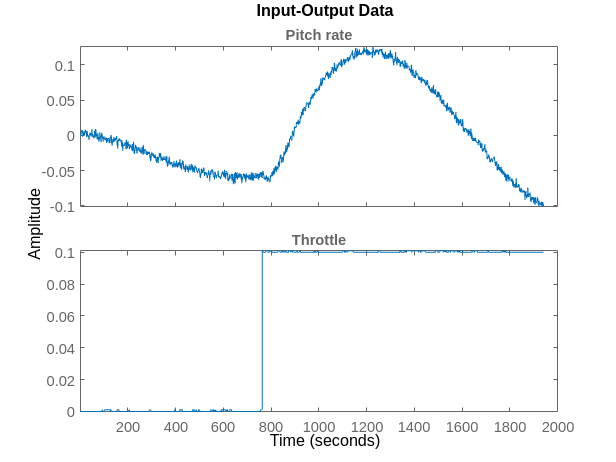

data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Pitch rate'})
plot(data)

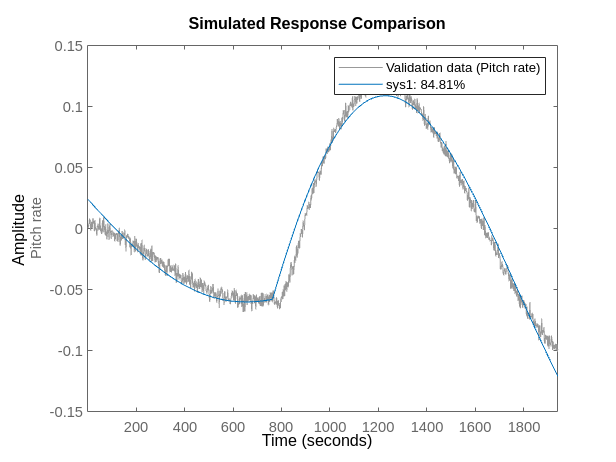

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

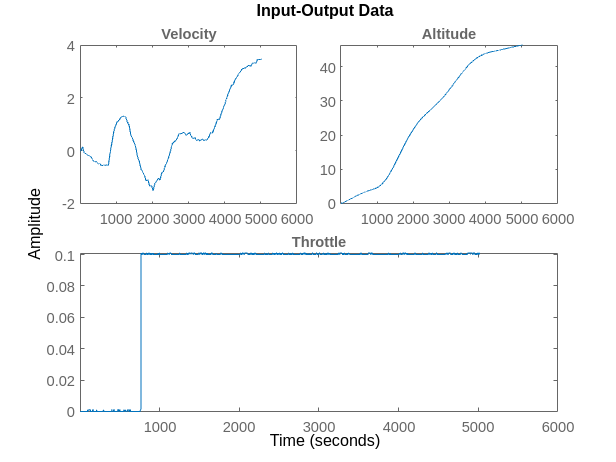

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Velocity', 'Altitude'}); %,'Evelator deflection'
plot(data)

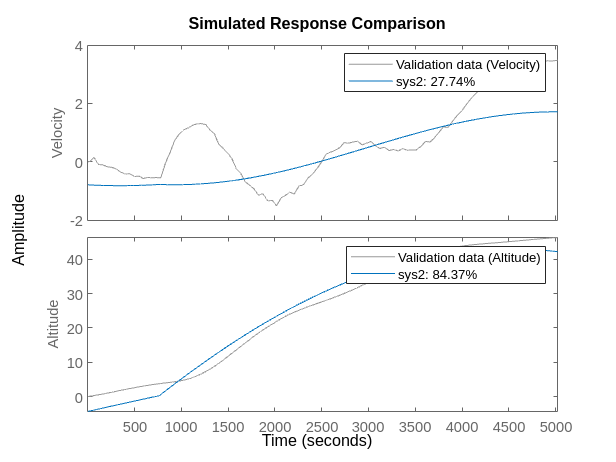

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

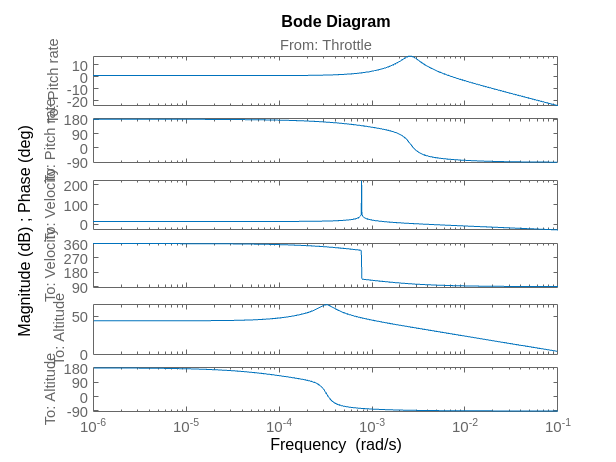

G1 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
bode(G1)

## System ID script - doublet

iodelay = 0;
u1 = throttle_s_doublet-0.0533;
u2 = elevator_s_doublet;
u3 = throttle_p_doublet-0.0533;
u4 = elevator_p_doublet;
airspeed_trim = vel_p_doublet(1,1);
alt_trim = alt_p_doublet(1,1);
pitch_rate_trim = q_s_doublet(1,1);
alpha_trim = aoa_s_doublet(1,1);
y1 = double(vel_p_doublet - airspeed_trim);
y3 = q_s_doublet - pitch_rate_trim;
y4 = double(aoa_s_doublet - alpha_trim);
y5 = double(alt_p_doublet - alt_trim);

### MIMO identification - short period mode

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1]%[1 2; 1 1];

nz = 1

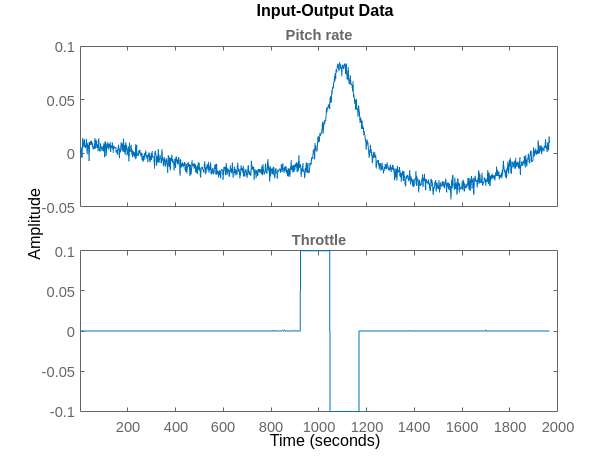

data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Pitch rate'})
plot(data)

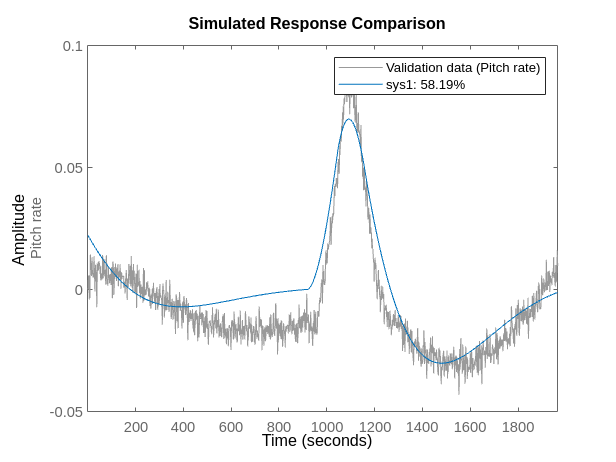

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

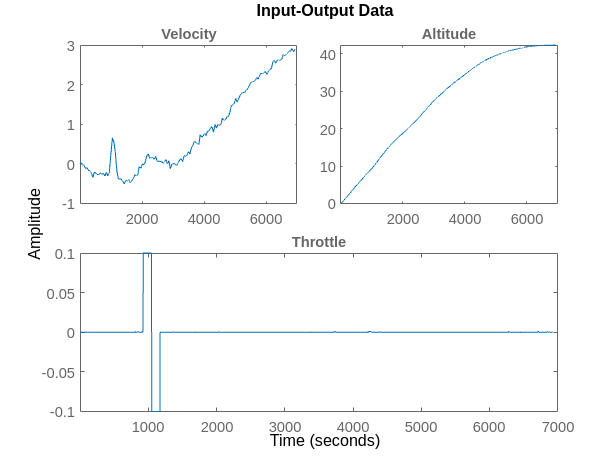

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

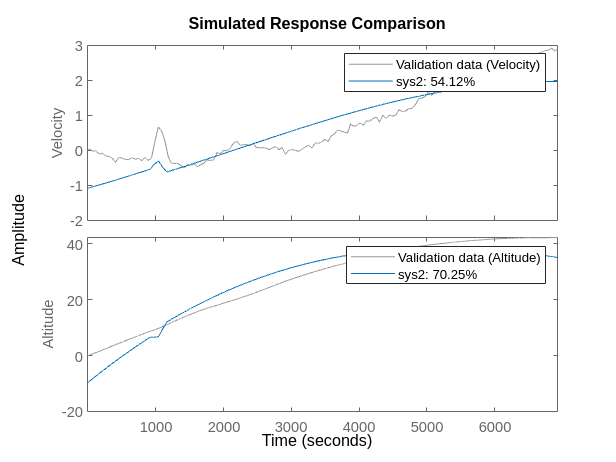

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G2_t = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G2_t =
 
  From input "Throttle" to output...
                  0.0007173 s + 8.844e-05
   Pitch rate:  ----------------------------
                s^2 + 0.006576 s + 2.911e-05
 
                  0.02168 s - 0.000158
   Velocity:  ----------------------------
              s^2 + 2.137e-08 s + 1.13e-07
 
                  -0.2067 s + 0.001143
   Altitude:  -----------------------------
              s^2 + 0.0002472 s + 6.453e-08
 
Continuous-time transfer function.



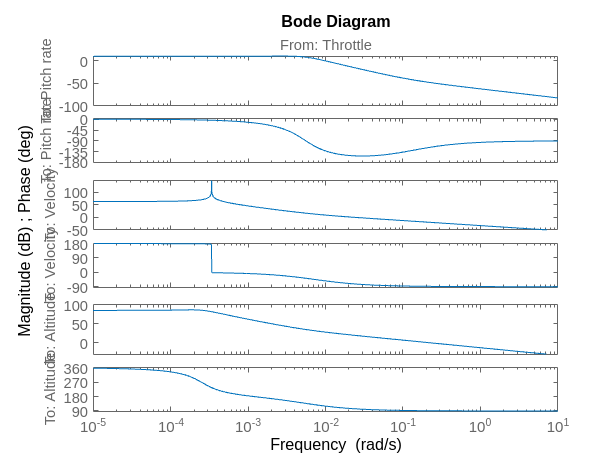

bode(G2_t)

## System ID script - sine sweep

iodelay = 0;
u1 = throttle_s_sine-0.0533;
u2 = elevator_s_sine;
u3 = throttle_p_sine-0.0533;
u4 = elevator_p_sine;
airspeed_trim = vel_p_sine(1,1);
alt_trim = alt_p_sine(1,1);
pitch_rate_trim = q_s_sine(1,1);
alpha_trim = aoa_s_sine(1,1);
y1 = double(vel_p_sine - airspeed_trim);
y3 = q_s_sine - pitch_rate_trim;
y4 = double(aoa_s_sine - alpha_trim);
y5 = double(alt_p_sine - alt_trim);

### MIMO identification - short period mode

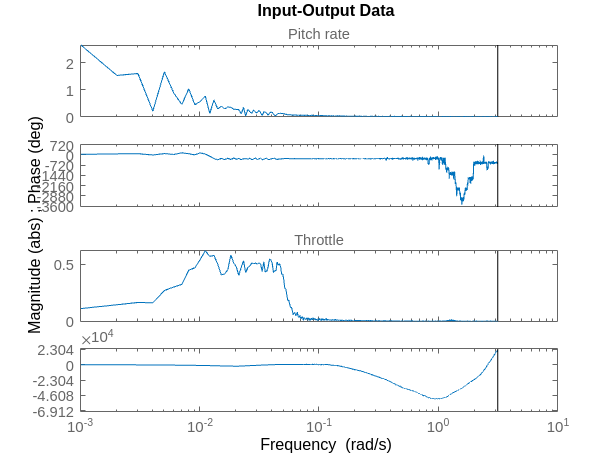

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1];%[1 2; 1 1];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Throttle'},'OutputName',{'Pitch rate'})
plot(data)

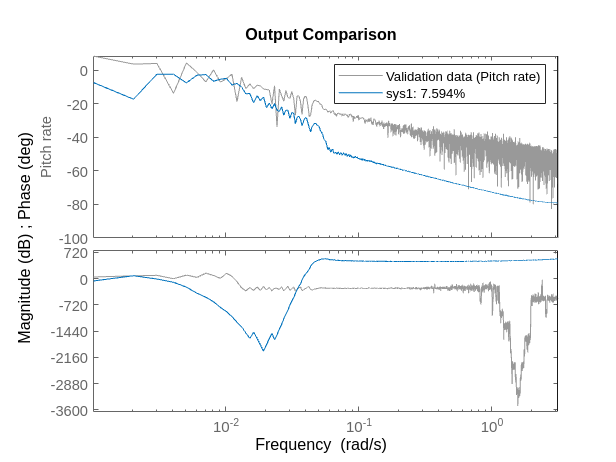

sys1_t= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

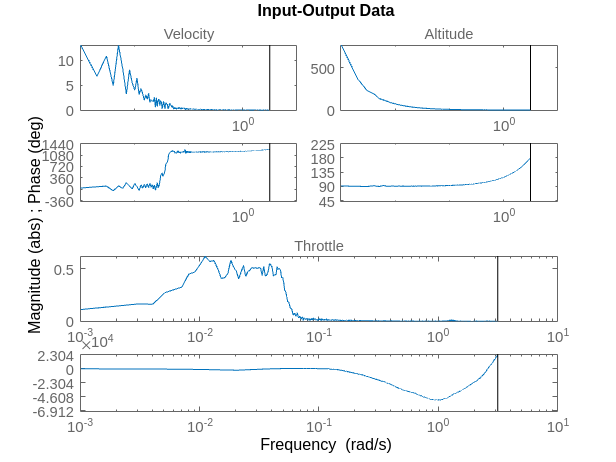

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Throttle'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

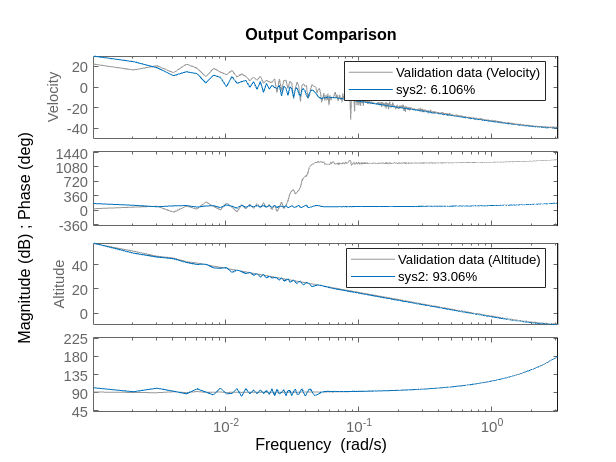

sys2_t= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G3_t = tf([sys1_t; sys2_t]) %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G3_t =
 
  From input "Throttle" to output...
                   -0.1387 s + 0.002088
   Pitch rate:  --------------------------
                s^2 + 0.6729 s - 0.0004717
 
                 0.08445 s - 0.0001464
   Velocity:  ---------------------------
              s^2 + 0.00217 s - 1.799e-06
 
                 -3.71e-05 s + 0.0001457
   Altitude:  -----------------------------
              s^2 - 8.427e-05 s + 4.548e-08
 
Continuous-time transfer function.



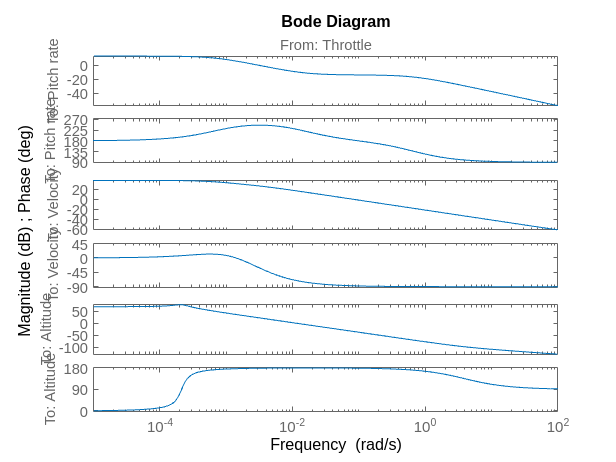

bode(G3_t)